# EEG脑机接口-SVM

## 数据导入

clear;clf;
%load common data
load("ChanName.mat");
load('Pair54.mat');
load('timeRawTrace.mat')
for i = 1:54
    Pair(i) = sprintf("Channel%d & %d",Pair54(i,1),Pair54(i,2));
end

%load personal data
for i = 1:4
    rawTracePerson = sprintf("Person%d\\Person%d\\rawTracePerson%d.mat",i,i,i);
    OSPerson = sprintf("Person%d\\Person%d\\OSPerson%d.mat",i,i,i);

    rawTracePerson_info = whos('-file', rawTracePerson);
    rawTracePerson_name = {rawTracePerson_info.name};
    OSPerson_info = whos('-file',OSPerson);
    OSPerson_name = {OSPerson_info.name};
    
    load(rawTracePerson);
    load(OSPerson);
    for j=1:length(rawTracePerson_name)
        eval(sprintf("%s_P%d = %s;",rawTracePerson_name{j},i,rawTracePerson_name{j}));
    end
  
    for j=1:length(OSPerson_name)
        eval(sprintf("%s_P%d = %s;",OSPerson_name{j},i,OSPerson_name{j}));
    end
    
end


#### 全四人,时频点

% 定义范围
lowerBound = 4;
upperBound = 15;
for no = 1:4
    % 使用逻辑索引提取满足条件的数据
    eval(sprintf("thetaindex%d = find(fOS_P%d>=lowerBound & fOS_P%d<= upperBound);",no,no,no));
    eval(sprintf("Timeindex%d = find(Time_P%d>=0 & Time_P%d<= 7);",no,no,no))
    eval(sprintf("thetaOS_P%d = OS_P%d(Timeindex%d,thetaindex%d,:,:);",no,no,no,no));
end
%将Track替换为match/nonmatch(1/0)
Track_all = [Track_P1,Track_P2,Track_P3,Track_P4];
isMatch_all = (Track_all<11)';
%10折交叉验证
% 定义交叉验证的折数
num_folds = 10;
% 初始化准确率向量
accuracies = zeros(num_folds, 1);
freq_OS_P1 = reshape(thetaOS_P1,[],40)';
freq_OS_P2 = reshape(thetaOS_P2,[],10)';
freq_OS_P3 = reshape(thetaOS_P3,[],40)';
freq_OS_P4 = reshape(thetaOS_P4,[],10)';
freq_OS = vertcat(freq_OS_P1,freq_OS_P2,freq_OS_P3,freq_OS_P4);
%全时频点PCA
k = 1; % 选择前 k 个主成分
features = zeros(40, k); % 存储提取的特征
[coeff, score, ~, ~, explained] = pca(freq_OS);
features = score(:, 1:k); 
% 进行交叉验证
indices = crossvalind('Kfold', length(isMatch_all), num_folds);
for fold = 1:num_folds
    % 划分训练集和测试集
    test_indices = (indices == fold);
    train_indices = ~test_indices;
    
    train_data = features(train_indices, :);
    train_labels = isMatch_all(train_indices);
    
    test_data = features(test_indices, :);
    test_labels = isMatch_all(test_indices);
    
    % 训练SVM模型
    svm_model = fitcsvm(train_data, train_labels,'KernelFunction',"rbf");
    
    % 预测测试集的标签
    predicted_labels = predict(svm_model, test_data);
    
    % 计算分类准确率
    accuracy = sum(predicted_labels == test_labels) / numel(test_labels);
    accuracies(fold) = accuracy;
    
end
average_accuracy = mean(accuracies);
fprintf('平均分类准确率: %.2f%%\n', average_accuracy * 100);

平均分类准确率: 56.00%


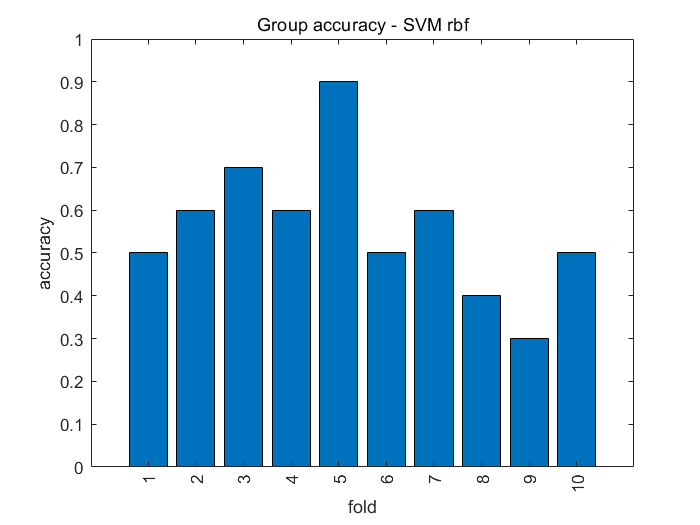

figure;
bar(accuracies);
title("Group accuracy - SVM rbf");
ylim([0,1]);
xlabel("fold");
ylabel("accuracy");
xticks(1:10);
xtickangle(90);

#### 全四人,时点

% 定义范围
lowerBound = 4;
upperBound = 15;
for no = 1:4
    % 使用逻辑索引提取满足条件的数据
    eval(sprintf("thetaindex%d = find(fOS_P%d>=lowerBound & fOS_P%d<= upperBound);",no,no,no));
    eval(sprintf("Timeindex%d = find(Time_P%d>=0 & Time_P%d<= 7);",no,no,no))
    eval(sprintf("thetaOS_P%d = squeeze(mean(OS_P%d(Timeindex%d,thetaindex%d,:,:),2));",no,no,no,no));
end
%将Track替换为match/nonmatch(1/0)
Track_all = [Track_P1,Track_P2,Track_P3,Track_P4];
isMatch_all = (Track_all<11)';
%10折交叉验证
% 定义交叉验证的折数
num_folds = 10;
accuracies = zeros(num_folds, 1);
freq_OS_P1 = reshape(thetaOS_P1,[],40)';
freq_OS_P2 = reshape(thetaOS_P2,[],10)';
freq_OS_P3 = reshape(thetaOS_P3,[],40)';
freq_OS_P4 = reshape(thetaOS_P4,[],10)';
freq_OS = vertcat(freq_OS_P1,freq_OS_P2,freq_OS_P3,freq_OS_P4);
%全时频点PCA
k = 1; % 选择前 k 个主成分
features = zeros(40, k); % 存储提取的特征
[coeff, score, ~, ~, explained] = pca(freq_OS);
features = score(:, 1:k); 
% 进行交叉验证
for no = 1:4
    eval(sprintf("isMatch_P%d = (Track_P%d<11)';",no,no));
    eval(springtf("indices_P%d = crossvalind('Kfold', length(isMatch_P%d), num_folds);"));
end

for fold = 1:num_folds
    for no = 1:4
        % 划分训练集和测试集
        eval(sprintf("test_indices_P%d = (indices_P%d == fold);"),no,no);
        eval(sprintf("train_indices_P%d = ~test_indices_P%d;"),no,no)
        
        train_data = features(train_indices, :);
        train_labels = isMatch_all(train_indices);
        
        test_data = features(test_indices, :);
        test_labels = isMatch_all(test_indices);
    end
    % 训练SVM模型
    svm_model = fitcsvm(train_data, train_labels,'KernelFunction',"rbf");
    
    % 预测测试集的标签
    predicted_labels = predict(svm_model, test_data);
    
    % 计算分类准确率
    accuracy = sum(predicted_labels == test_labels) / numel(test_labels);
    accuracies(fold) = accuracy;
end

average_accuracy = mean(accuracies);
fprintf('平均分类准确率: %.2f%%\n', average_accuracy * 100);

平均分类准确率: 56.00%


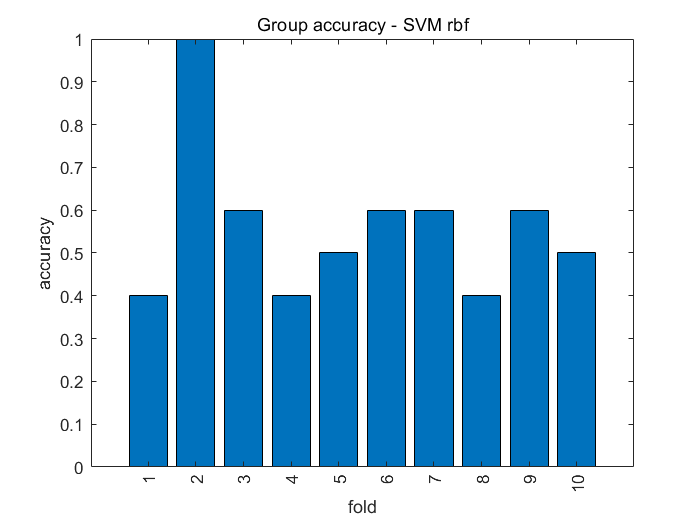

figure;
bar(accuracies);
title("Group accuracy - SVM rbf");
ylim([0,1]);
xlabel("fold");
ylabel("accuracy");
xticks(1:10);
xtickangle(90);